# Power-Split Hybrid Electric Vehicle Model with Direct Input

Copyright 2021 The MathWorks, Inc.

## Open the model

mdl = "PowerSplitHEV_DirectInput";
if not(bdIsLoaded(mdl)), open_system(mdl); end

% Run setup script
PowerSplitHEV_DirectInput_setup

## Load inputs

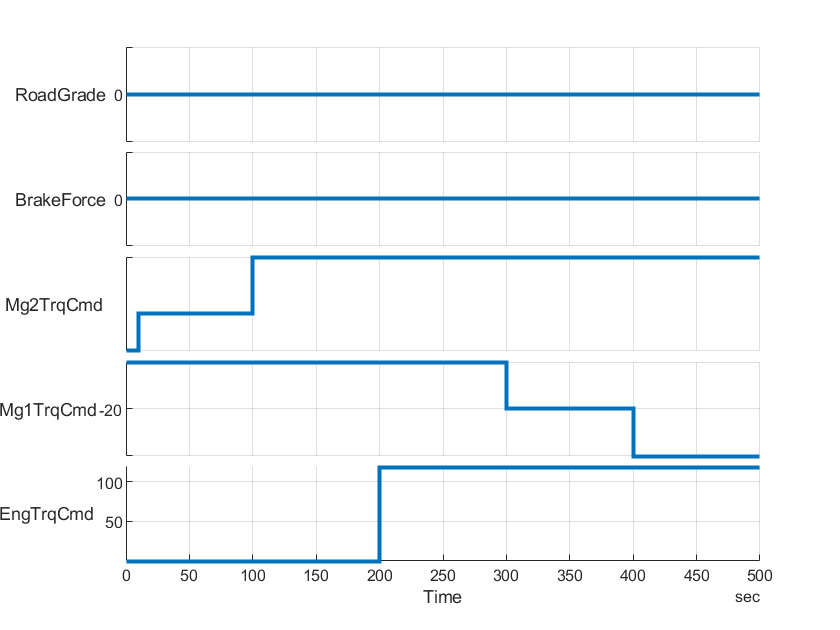

fig = figure;
[inputSignals_DirectIn, inputBus_DirectIn, t_end] = ...
  PowerSplitHEV_DirectInput_inputs2( ...
    "PlotParent",fig, "InputPattern","power_split_drive_2" );

## Run simulation

% Set initial conditions

initial.highVoltageBatterySOC_pct = 85;
initial.hvBatteryCharge_Ah = batteryHighVoltage.nominalCharge_Ah * initial.highVoltageBatterySOC_pct/100;

initial.vehicleSpeed_kph = 0;
initial.motorGenerator2_speed_rpm = 0;
initial.motorGenerator1_speed_rpm = 0;
initial.engine_speed_rpm = 0;
initial.engine_torque_Nm = 0;

% Override block parameters

% Set Simulation Input
in = Simulink.SimulationInput(mdl);
in = in.setModelParameter('StopTime',num2str(t_end));

% Run simulation
out = sim(in);

## Visualize Simulation Result

Vehicle

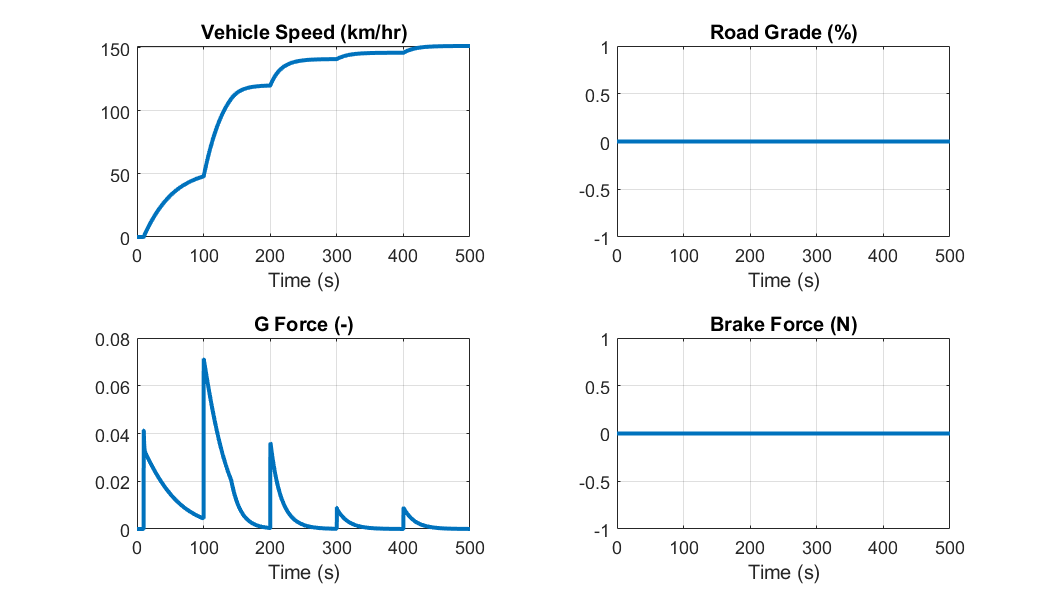

fig = figure;
PowerSplitHEV_DirectInput_plot_result_vehicle( "Dataset",out.logsout, "PlotParent",fig );

High Voltage Battery

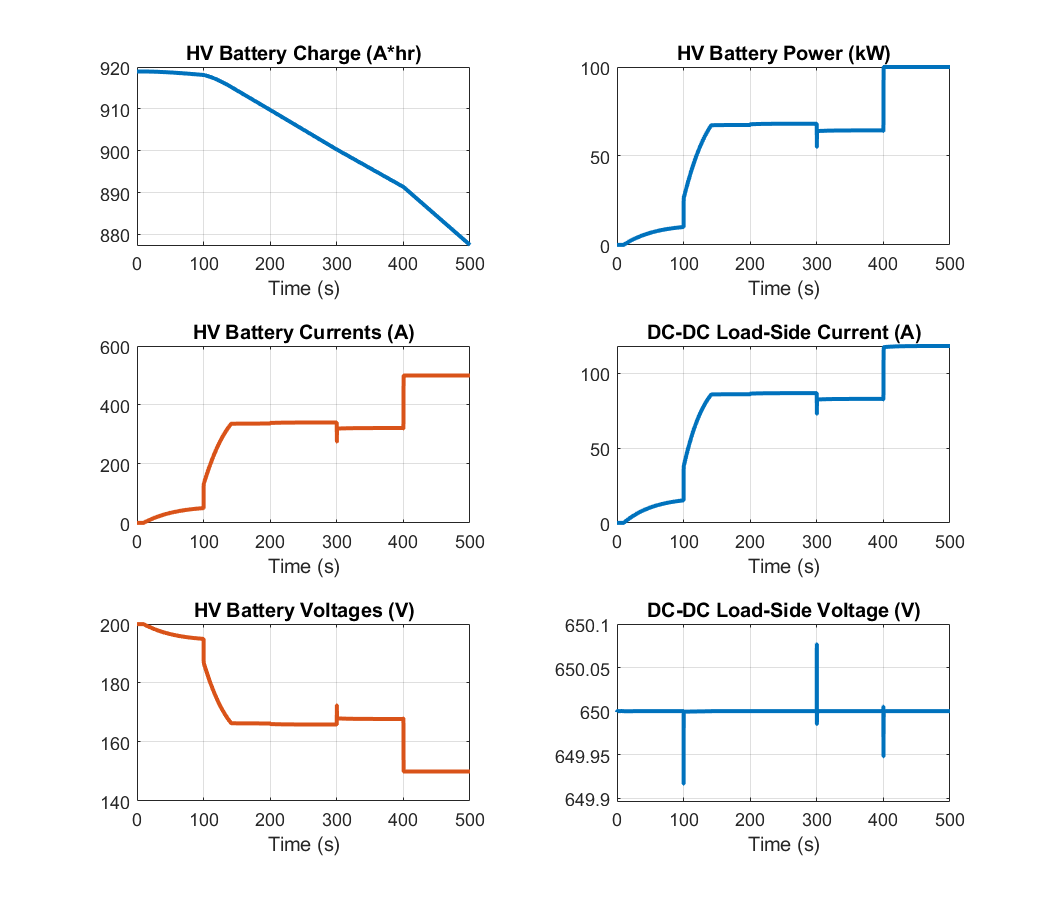

fig = figure;
PowerSplitHEV_DirectInput_plot_result_hvbattery( "Dataset",out.logsout, "PlotParent",fig );

Power-Split Drive Unit

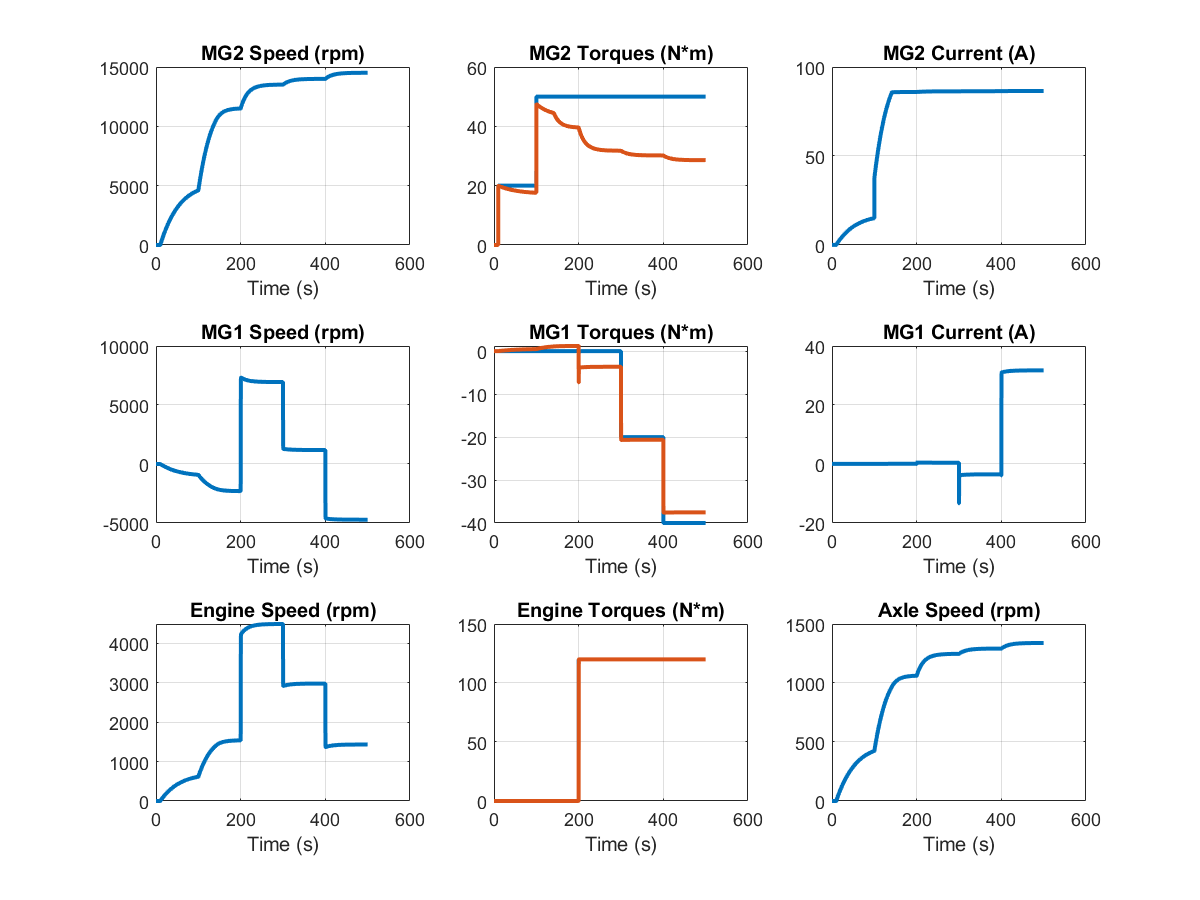

fig = figure;
PowerSplitHEV_DirectInput_plot_result_powersplit( "Dataset",out.logsout, "PlotParent",fig );